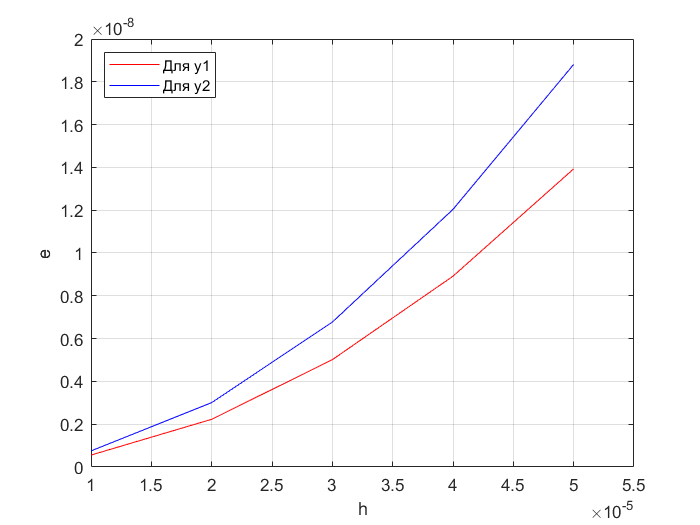

clear
clc
close all
a = 0;
b = 2;
h_vec = 0.00001:0.00001:0.00005;
e1 = zeros(1, length(h_vec));
e2 = zeros(1, length(h_vec));
Func = @(t, Y) [Y(1)/(2+2*t)-2*t*Y(2); Y(2)/(2+2*t)+2*t*Y(1)];

for i = 1:length(h_vec)
    x = a:h_vec(i):b;
    y1_ex = cos(x.*x).*sqrt(1+x);
    y2_ex = sin(x.*x).*sqrt(1+x);
    Y = zeros(2, length(x));
    Y(1,1) = y1_ex(1);
    Y(2,1) = y2_ex(1);
    for j = 1:length(x)-1
        K1 = Func(x(j), Y(:, j));
        K2 = Func(x(j)+h_vec(i), Y(:, j)+h_vec(i)*K1);
        Y(:, j+1) = Y(:, j) + h_vec(i)*(0.5*K1+0.5*K2);
    end
    e1(i) = (norm(y1_ex - Y(1, :),"inf"));
    e2(i) = (norm(y2_ex - Y(2, :),"inf"));
end


plot(h_vec, e1, 'r', h_vec, e2,'b')
xlabel("h")
ylabel("e") 
grid on
legend('Для y1', 'Для y2', 'Location','northwest')

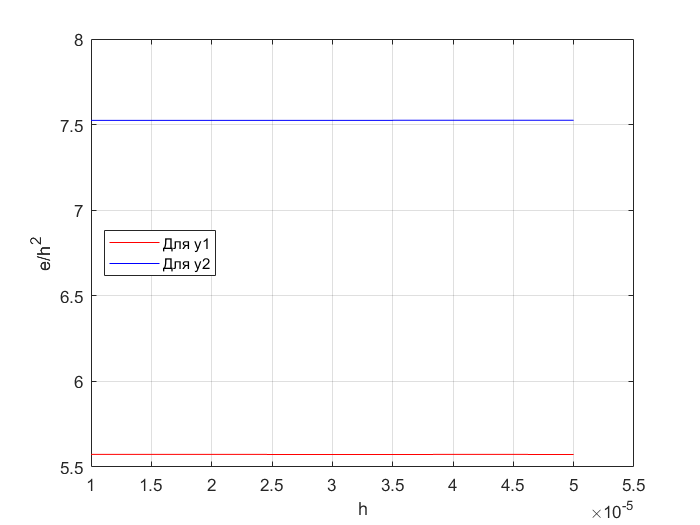



plot(h_vec, e1./h_vec.^2, 'r', h_vec, e2./h_vec.^2, 'b')
xlabel("h")
ylabel("e/h^2") 
legend('Для y1', 'Для y2', 'Location','west')
grid on